n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 3;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

p_vec =  [500, 1000,1500,2000,2500,3000,3500,4000, 4500, 5000];
n_rep = 100;
n_pararell = 10;
n_p_chunk = 1;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end

tic
% parallel for loop
parfor w = 1 : n_pararell
    for i = 1:length(p_vec_chunk{w})
    p = p_vec_chunk{w}(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
        % iterate
 
        clustering_acc_mat_chunk{w}(j, i) = iterative_kmeans_hc_init_ver_01_11_24_parallel(x, sigma, K,  n_iter, rounding, cluster_true);
    end
end
end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.0

toc

Elapsed time is 2812.176418 seconds.


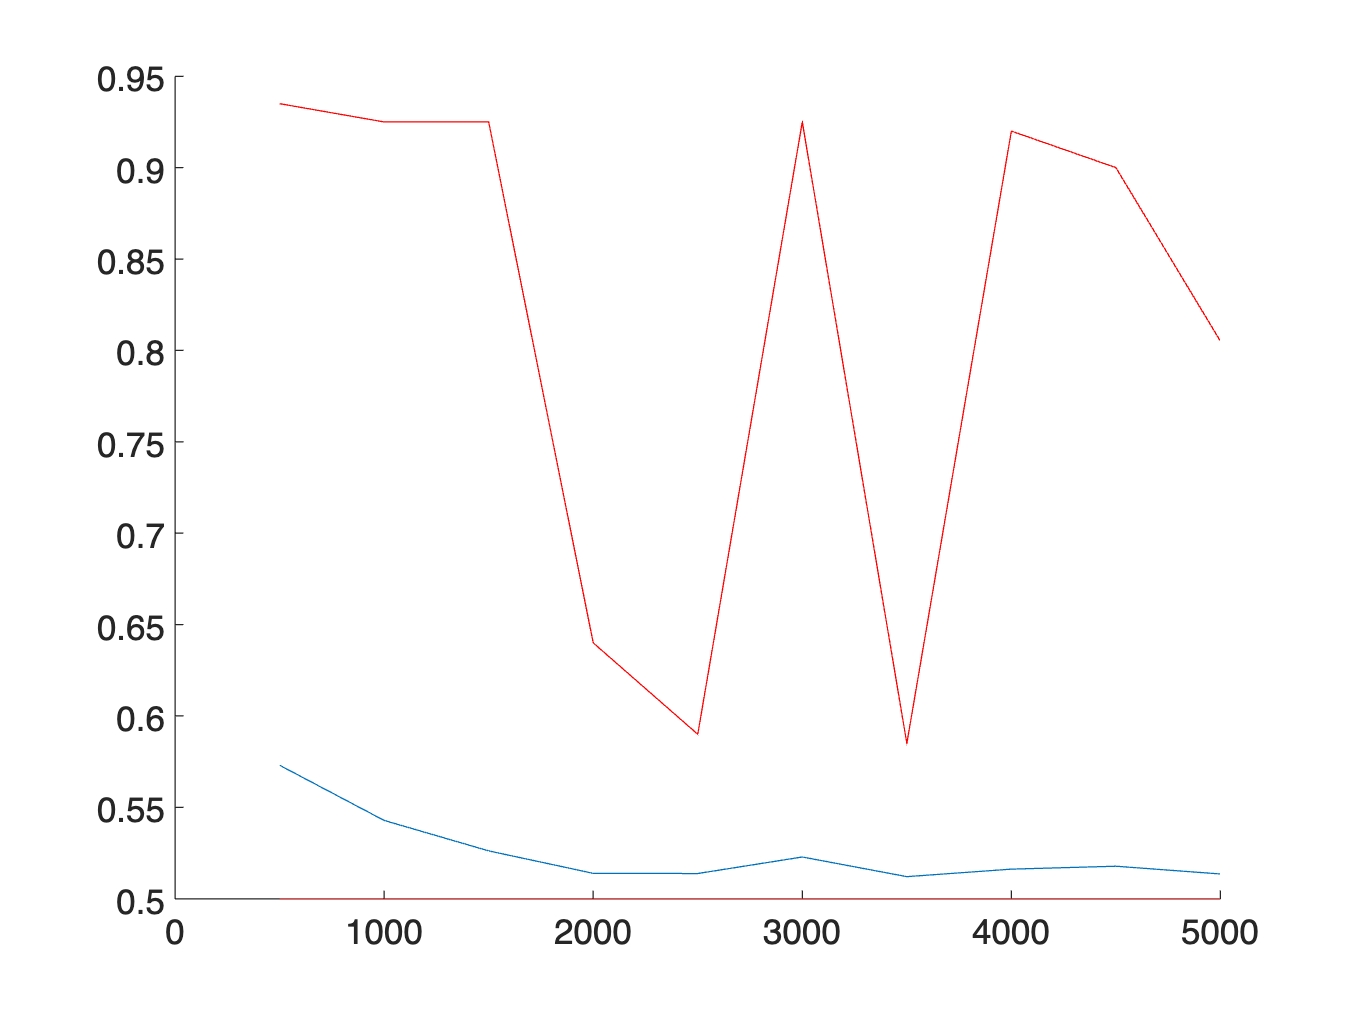

clustering_acc_mat = [];
for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
    x = p_vec;                     
    y = mean(clustering_acc_mat,1);
    y_max = max(clustering_acc_mat);
    y_min = min(clustering_acc_mat);
end

figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off

result = [[500, 1000,1500,2000,2500,3000,3500,4000, 4500, 5000]',mean(clustering_acc_mat,1)']

result = 1.0e+03 *

    0.5000    0.0006
    1.0000    0.0005
    1.5000    0.0005
    2.0000    0.0005
    2.5000    0.0005
    3.0000    0.0005
    3.5000    0.0005
    4.0000    0.0005
    4.5000    0.0005
    5.0000    0.0005


csvwrite('/Users/jmmoon/Documents/GitHub/sparse_kmeans/SDPNAL+v1.0/summary_hc_sep_3.csv',result)
